# Task:  **Lagrangian approach for deriving Eoms for Quadcopter**

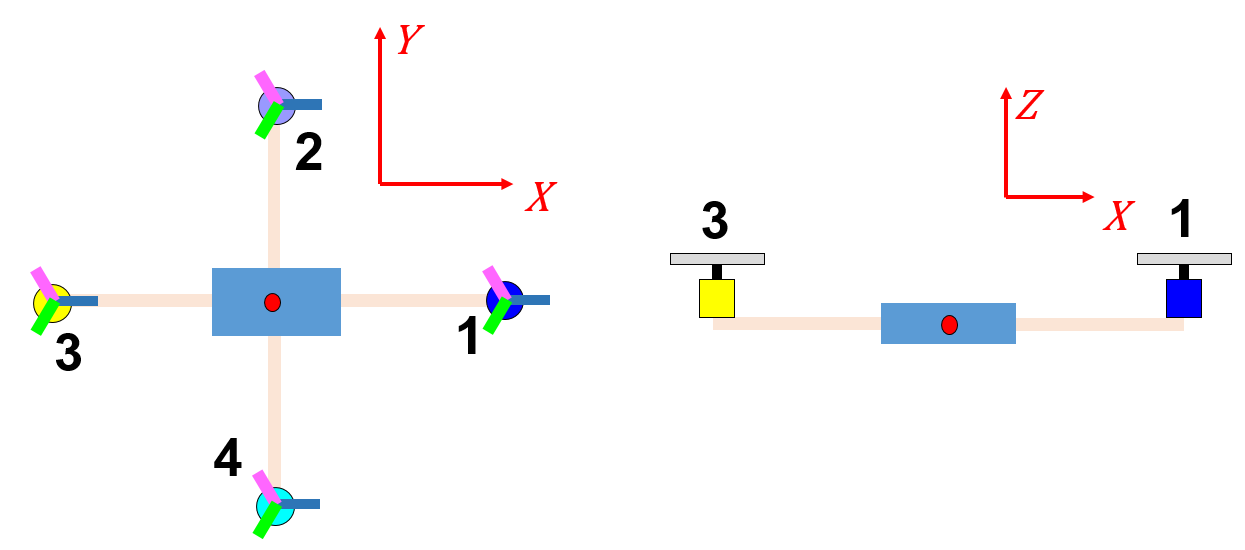

In this task we're going to look at how the Lagrangian Dynamics approach can be used to derive the equations of motion of a Rigid Body.  Steps that we'll take will include:

- What is a PASSIVE rotation matrix ?

- How do i construct a Direction Cosine Matrix (DCM) from a given rotation sequence ?

- What is the relationship between BODy rates and EULER rates ?

- What is the KE and PE of just the airframe ?

- What is the KE and PE of each rotor+Propeller assembly ?

- Apply Lagrange's equation to derive the system EoMs

**Euler-Lagrange equations:**

The Euler-Lagrange formula will be used to derive the equations of motion for a Rigid Body, and it has the form:

                           $\frac{d}{dt}\frac{\partial L}{\partial \dot{q}_k} - \frac{\partial L}{\partial q_k} = Q_k $     for     $k=1,2, \dots, n$

where  *n* is the DOF of the system, {$q_1, q_2, \dots, q_n$} is a set of generalized coordinates, {$Q_1, Q_2, \dots, Q_n$} is the set of generalized forces associated with those coordinates, and the Lagrangian:  ***L***** =  *****T***  ***-***  ***V****,* is defined as the difference between the kinetic and potential energy of the  *n-* DOF system. The Generalised forces can also be defined in terns of the non conservative forces and torques acting on the multibody system.  The formula for the generalised forces acting on the system is:


$$Q_k = 
\sum_{i=1}^{Nf_{nc}}
\pmatrix{
\vec{F_i} \thinspace . \thinspace \frac{\partial \vec{v \thinspace _i}}{\partial \dot{q \thinspace}_k}
}  \enspace + \enspace
\sum_{j=1}^{N\tau_{nc}}
\pmatrix{
\vec {\tau_j} \thinspace . \thinspace \frac{\partial \vec{\omega \thinspace _j}}{\partial \dot{q \thinspace}_k}
}
$$


where:

- $Q_k$     :    is the generalised force associated with the $k^{th}$ generalised co-ordinate $q_k$

- $Nf_{nc}$ :    is the number of active NON conservative forces

- $N\tau_{nc}$:    is the number of active NON conservative TORQUES

- $\vec{v_i}$    :    is the velocity vector of the point associated with the applied force.

- $\vec{\omega_i}$   :    is the angular velocity about the point associated with the applied torque. 

`Bradley Horton : 25-Sep-2017, bradley.horton@mathworks.com.au`

  Change History:

- `20-Sep-2019 - `a local `cross()` function is defined as a SUBFUNCTION in this script.  This ensures consistent behavior with R2019b

# **Prework - part A :   Euler angles and Euler rates**

For a refresher on the concept of Euler rates and their relationship to the angular velocity of a body, please review the stand alone Live script called:

- `bh_review_Euler_rates_and_wb.mlx `

Assume that we orientate a body in space via 3 successive rotations in the following order:

- R1Z occurs 1st about the LOCAL **Z** body axis $(\phi)$, aka **YAW**

- R2Y occurs 2nd about the LOCAL **Y** body axis $(\theta)$, aka **PITCH**

- R3X occurs 3rd about the LOCAL **X** body axis $(\psi)$, aka **ROLL**

Two key concepts described in the above script are:

- 
$$A \times   \pmatrix{ \phi_{dot} \cr \theta_{dot} \cr \psi_{dot} }  =  \pmatrix{\omega_x \cr \omega_y \cr \omega_z}  $$


- $\bf ^Bv = {^BR_G} \enspace \times \enspace {^Gv}$      where     $\bf ^BR_G = R3X(\psi_x) \enspace \times \enspace 
R2Y(\theta_y) \enspace \times \enspace R1Z(\phi_z)$

We have implemented the calculations for $\bf ^BR_G$ and  **A **into the Live Function `bh_func_calc_euler_bRg_ZYX`

syms phi theta psi
 
if( string( version('-release'))   >= "2018a" )  % relational comparison with strings is done lexicographically (ie alphabetical)
    [bRg, A] = bh_func_calc_euler_bRg_ZYX()    
else
    [bRg, A] = LOC_collect_euler_concepts()
end

$$bRg = \left(\begin{array}{ccc} \cos\left(\varphi \right)\,\cos\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\varphi \right) & -\sin\left(\theta \right)\\ \cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\psi \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right)+\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\psi \right)\\ \sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right) & \cos\left(\psi \right)\,\cos\left(\theta \right) \end{array}\right)$$

$$A = \left(\begin{array}{ccc} -\sin\left(\theta \right) & 0 & 1\\ \cos\left(\theta \right)\,\sin\left(\psi \right) & \cos\left(\psi \right) & 0\\ \cos\left(\psi \right)\,\cos\left(\theta \right) & -\sin\left(\psi \right) & 0 \end{array}\right)$$

# **Getting ready for the Lagrangian approach:**

   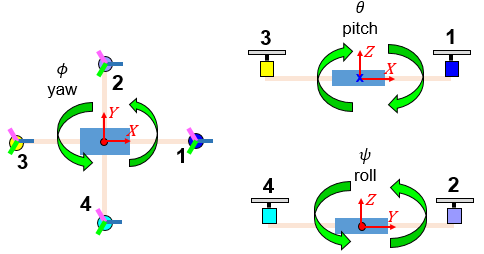

**ATTENTION:**

In our Lagrangian derivation we'll make the following assumptions:

- The electric motors are in semi steady state, ie: we'll assume that $K_a \ldotp i\;-\;b\ldotp \omega -\tau_{\textrm{DRAG}} =0$

- This means that the motor reaction torque applied to the quadcopter AIRFRAME is equivalent to $\tau_{\textrm{DRAG}}$

Euler angles for the vehicles airframe:

syms        Phi(t)      Theta(t)       Psi(t)    
syms    THE_Phi     THE_Theta      THE_Psi

BODY {B}-frame Thrusts and yaw torques applied to the airframe:

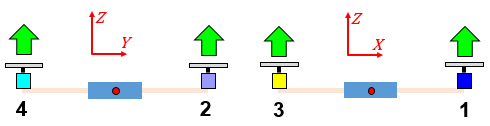

syms Tbz_1  Tbz_2  Tbz_3  Tbz_4
syms Mbz_1  Mbz_2  Mbz_3  Mbz_4

INERTIAL {G}-frame co-ordinates of vehicles center of mass (CoM):

syms         X(t)      Y(t)      Z(t)
syms     THE_X     THE_Y     THE_Z

Inertias, mass and gravity of the Airframe body (this excludes the spinning rotor and propeller assemblies):

syms I_xx I_xy I_xz I_yy I_yz I_zz
syms m
syms g

I = [  I_xx,  I_xy,  I_xz;
       I_xy,  I_yy,  I_yz;
       I_xz,  I_yz,  I_zz   ];

Inertia and mass of ***a single*** spinning propeller assembly:

syms Iprop_xx Iprop_xy Iprop_xz Iprop_yy Iprop_yz Iprop_zz
syms mprop

Iprop = [  Iprop_xx,  Iprop_xy,  Iprop_xz;
           Iprop_xy,  Iprop_yy,  Iprop_yz;
           Iprop_xz,  Iprop_yz,  Iprop_zz   ];

The spin velocities of the propeller assembly relative to the BODY fixed airframe {B}-FRAME:

syms wMOT_1  wMOT_2  wMOT_3  wMOT_4

wMOT_list = [wMOT_1;  wMOT_2;  wMOT_3;  wMOT_4];

For the next 2 lists, it's important that we use the same ordering for our symbols:

actual_list_SYM_pos = [    Phi(t),      Theta(t),      Psi(t),      X(t),      Y(t),      Z(t)];
holder_list_SYM_pos = [THE_Phi,     THE_Theta,     THE_Psi,     THE_X,     THE_Y,     THE_Z   ];                             

In the previous section we derived the relationship between body rates and Euler rates.  So let's just insert our NEW symbols.  Recall that:         $\matrix{
A & \times & \pmatrix{\dot{\matrix{\phi}} \cr \dot{\matrix{\theta}}  \cr \dot{\matrix{\psi}}  } & = & \pmatrix{ ^B\omega_x \cr ^B\omega_y \cr ^B\omega_z} 

}$  

                % OLD_list          NEW_list
A     = subs(A, [phi, theta, psi], [Phi(t), Theta(t), Psi(t)])

$$A = \left(\begin{array}{ccc} -\sin\left(\Theta \left(t\right)\right) & 0 & 1\\ \cos\left(\Theta \left(t\right)\right)\,\sin\left(\Psi \left(t\right)\right) & \cos\left(\Psi \left(t\right)\right) & 0\\ \cos\left(\Psi \left(t\right)\right)\,\cos\left(\Theta \left(t\right)\right) & -\sin\left(\Psi \left(t\right)\right) & 0 \end{array}\right)$$


e_dot = [ diff(Phi(t),   t);
          diff(Theta(t), t); 
          diff(Psi(t),   t) ]

$$e\_dot = \left(\begin{array}{c} \frac{\partial }{\partial t}\Phi \left(t\right)\\ \frac{\partial }{\partial t}\Theta \left(t\right)\\ \frac{\partial }{\partial t}\Psi \left(t\right) \end{array}\right)$$


w     = A * e_dot;      

Define the Direction Cosine Matrix using our new symbols:

                          % OLD_list          NEW_list
bRg_again = subs(bRg, [phi, theta, psi], [Phi(t), Theta(t), Psi(t)]);
gRb_again = (bRg_again).';

# Translational and Angular velocities and Altitude:

Say our Quadcopter looks like this:

Let's decompose our quadcopter into 5 rigid bodies:

- $1\;x\;\textrm{body}\longrightarrow$ : the airframe

- $4\;x\;\textrm{body}\longrightarrow$ : each of the rotating propeller+rotor assemblies

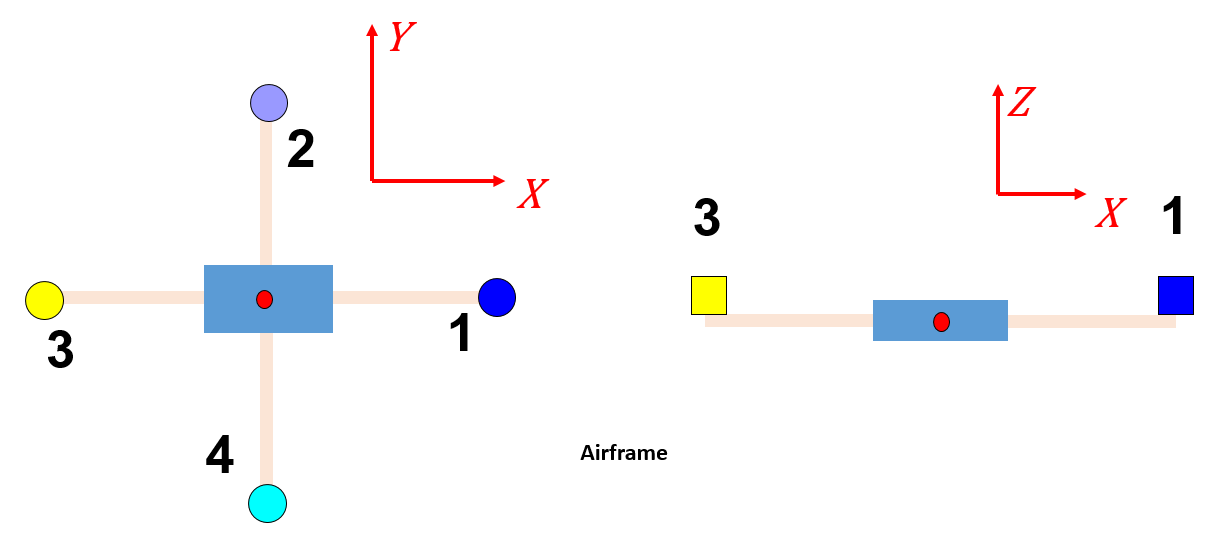            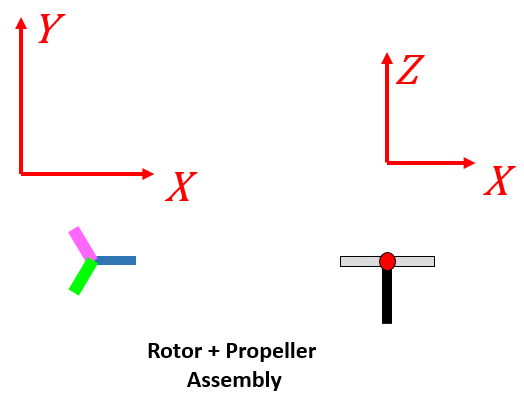

And Let's say that we know the Center of Mass of each of these bodies.  So what we need to do next is to compute the Kinetic and Potential enegies of each of these components.  To do this, we'll need to know the following for each of our bodies:

- $^G_Gv$ *, CoM translational velocity vector is expressed** in components of the {G}-frame*

- $^B_G\omega$*, angular velocity vector expressed in components of the {B}-frame*

- ${^GZ}$, CoM altitude *expressed in components of the {G}-frame*

**The AIRFRAME:**

v_com_airframe = [ diff(X(t),t);  diff(Y(t),t);  diff(Z(t),t) ];
w_airframe     = formula(  w  );
Z_airframe     = formula(  Z  );

**The PROPELLER assemblies :**

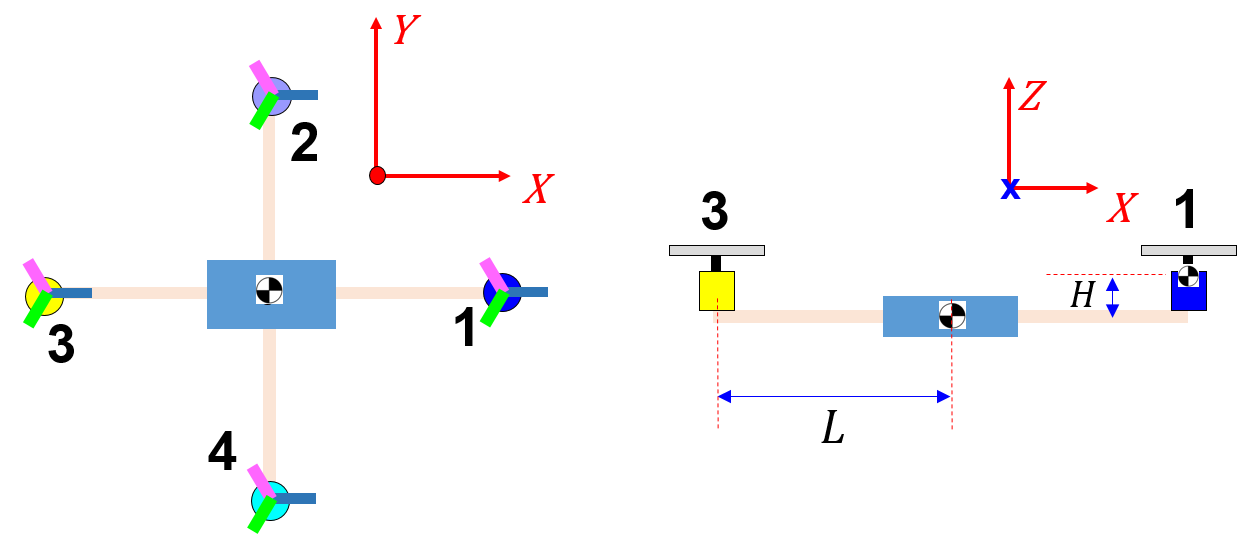

Define lengths from airframe CoM to each propeller:

syms     cg_to_mot_L                  cg_to_mot_H
L1_len = cg_to_mot_L;        H1_len = cg_to_mot_H;
L2_len = cg_to_mot_L;        H2_len = cg_to_mot_H;
L3_len = cg_to_mot_L;        H3_len = cg_to_mot_H;
L4_len = cg_to_mot_L;        H4_len = cg_to_mot_H;

So the vectors from the airframe's CoM to each CoM of the rotor+propeller assemblies are expressed by each column in the matrix below - the vectors are expressed in components of the airframe body fixed {B}-frame.

            % mot_#1    mot_#2      mot_#3     mot_#4
br_mat = [    L1_len,        0,    -L3_len,         0;
                   0,   L2_len,          0,   -L4_len;
              H1_len,   H2_len,     H3_len,    H4_len;   ];           

Now do the calculations:

- $^G_Gv$ *, CoM translational velocity vector is expressed in components of the {G}-frame*

- $^B_G\omega$*, angular velocity vector expressed in components of the {B}-frame*

- ${^GZ}$, CoM altitude *expressed in components of the {G}-frame*

for kk=1:4
    %-------------------------------------------------------    
    % compute local velocity due to rotation
    r              = br_mat(:,kk);
    vb_local       = formula( cross( w_airframe, r)  ); % == w x r
    % combine with airframe's CoM velocity
    v_air          = formula( v_com_airframe ); 
    vg             = v_air + gRb_again*vb_local; 
    v_prop_com_mat(:,kk)     = formula( vg );
    %-------------------------------------------------------
    tmp_rg           = formula( gRb_again * r );
    Z_prop_list(kk)  = formula(Z) +  tmp_rg(3);
    %-------------------------------------------------------
    w_prop_mat(:,kk) = formula(w_airframe) + [0;0;wMOT_list(kk)];    
end              

# The system KE and PE:

Next we'll use our previously derived expressions for  velocities and use them to define the "system" Kinetic Energy for our machine.  Because we've attached our BODY frames to the **centre of masses** of each body, the kinetic energy for the $i^{\textrm{th}}$ body can be stated as:


$${\textrm{KE}}_i =\;\frac{1}{2}{v_{{\textrm{cm}}_i }^T {\ldotp m}_i } {\;\ldotp v}_{{\textrm{cm}}_i } \;\;\;+\;\;\;\;\;\frac{1}{2}\ldotp \omega_{B_i }^T \ldotp \left\lbrack I_{{\textrm{cm}}_i } \right\rbrack \ldotp \omega_{B_i }$$


The total system kinetic energy is then just the sum of the "*N*" individual kinetic energies.   Similarly we can define our "system" Potential Energy as the sum of the "*N*" individual potential energies

- ${\textrm{KE}}_{\textrm{system}} =\;\sum_{i=1}^N {\textrm{KE}}_i$       and       ${P\mathrm{E}}_{\textrm{system}} =\;\sum_{i=1}^N {P\mathrm{E}}_i$

Start with the **airframe**:

KE = (1/2)*(v_com_airframe.')*m*(v_com_airframe)  + ...
     (1/2)*(    w_airframe.')*I*(    w_airframe) ;
 
PE = m*g*Z_airframe;

And then add the contributions from our 4 **propeller assemblies**:

for kk=1:4
    v_tmp = v_prop_com_mat(:,kk);
    w_tmp = w_prop_mat(:,kk);
    Z_tmp = Z_prop_list(kk);
    
    KE    = KE + (1/2)*(v_tmp.')*mprop*(v_tmp)  + ...
                 (1/2)*(w_tmp.')*Iprop*(w_tmp) ; 
             
    PE    = PE + mprop*g*Z_tmp;
end

# Prepare for the Computation of the Generalised Forces:

# 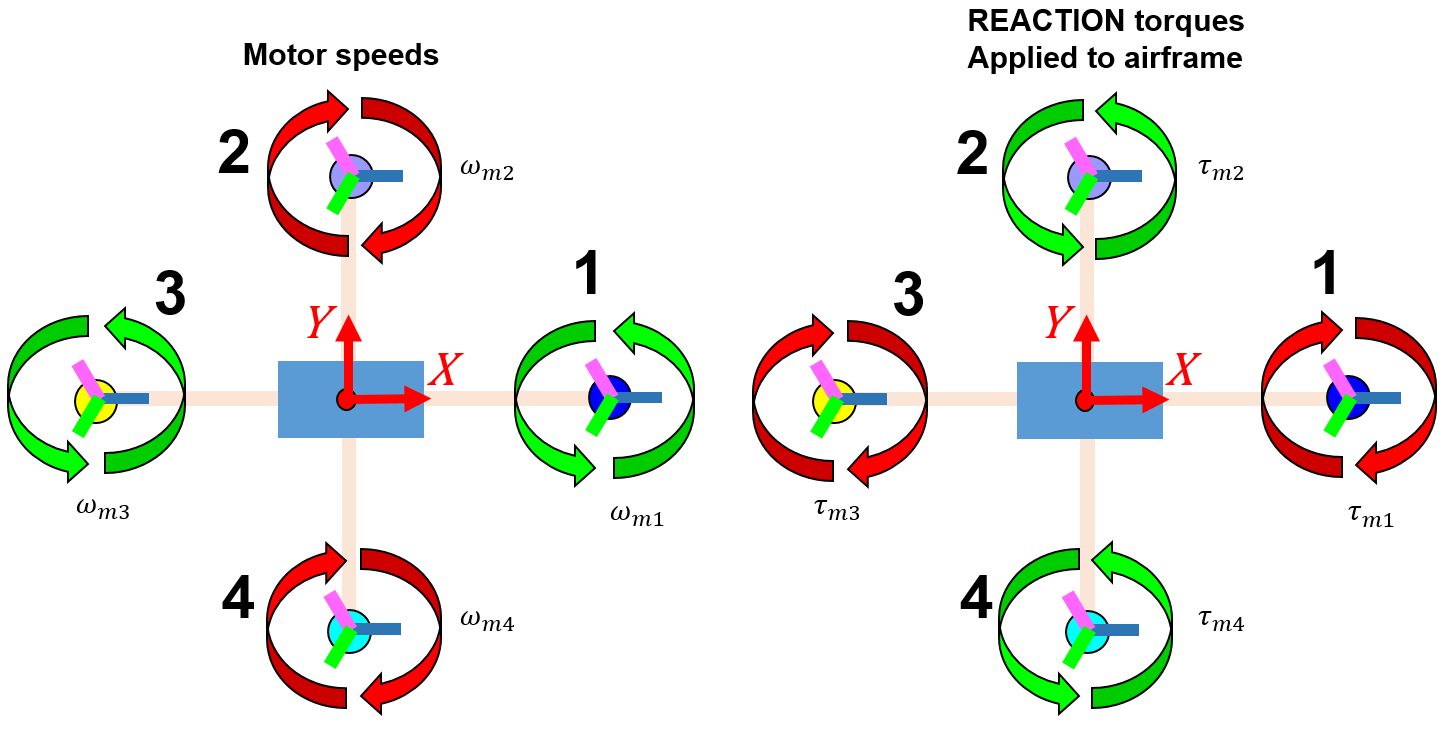 

Shortly we'll calculate the generalised force *Q* :


$$Q_k = 
\sum_{i=1}^{Nf_{nc}}
\pmatrix{
\vec{F_i} \thinspace . \thinspace \frac{\partial \vec{v \thinspace _i}}{\partial \dot{q \thinspace}_k}
}  \enspace + \enspace
\sum_{j=1}^{N\tau_{nc}}
\pmatrix{
\vec {\tau_j} \thinspace . \thinspace \frac{\partial \vec{\omega \thinspace _j}}{\partial \dot{q \thinspace}_k}
}
$$


First we'll define the **yawing Torques** acting on the airframe and the angular velocity of the airframe: 

 NOTE:  the consistency of the frames for expressing $M$and $\omega$

- The moment vectors are expressed in **components of the BODY frame**

- The angular velocity vectors are expressed in **components of the BODY frame**

F_mat1 = [            0,          0,           0,           0;
                      0,          0,           0,           0;
                  Mbz_1,      Mbz_2,       Mbz_3,       Mbz_4;  ];
        
v_mat1 = [  w_airframe,  w_airframe,  w_airframe,  w_airframe]; 
v_mat1 = formula( v_mat1 ); % make things SYM not SYMFUN

And we also have the THRUST forces acting on the airframe which we need to convert into the {G}-frame.  The velocities at the point of application of these Forces are also expressed in {G}-frame components:

F_mat2 = gRb_again * ...
                    [     0,       0,       0,       0;
                          0,       0,       0,       0;
                      Tbz_1,   Tbz_2,   Tbz_3,   Tbz_4;  ];
        
v_mat2 = [    v_prop_com_mat ];  

 NOTE: the consistency of the frames for expressing $F$and $v$

- The Force vectors are expressed in **components of the INERTIAL frame**

- The velocity vectors are expressed in **components of the INERTIAL frame**

v_mat2 = formula( v_mat2 ); % make things SYM not SYMFUN
F_mat2 = formula( F_mat2 ); % make things SYM not SYMFUN

Combine these Torques and Forces into a single matrix and do the same for the translational and rotational velocities:

F_mat = [F_mat1, F_mat2];
v_mat = [v_mat1, v_mat2];

# Apply Lagrange's equation  

To derive the equations of motion for our machine, "all" we need to do is a series of derivative calculations according to Lagrange's equation:

 $\frac{d}{dt}\frac{\partial L}{\partial \dot{q}_k} - \frac{\partial L}{\partial q_k} = Q_k $       where:      $Q_k = 
\sum_{i=1}^{Nf_{nc}}
\pmatrix{
\vec{F_i} \thinspace . \thinspace \frac{\partial \vec{v \thinspace _i}}{\partial \dot{q \thinspace}_k}
}  \enspace + \enspace
\sum_{j=1}^{N\tau_{nc}}
\pmatrix{
\vec {\tau_j} \thinspace . \thinspace \frac{\partial \vec{\omega \thinspace _j}}{\partial \dot{q \thinspace}_k}
}
$

Where:

- *L = KE - PE, *is our system lagrangian

- $q_k = \{ \Phi, \Theta, \psi, {^GX}, {^GY}, {^GZ} \}$ are the generalised co-ordinates 

- $Q_k$ are the generalised forces (Forces and Torques) for our system

Recall our list of generalised co-ordinates:

actual_list_SYM_pos

$$actual\_list\_SYM\_pos = \left(\begin{array}{cccccc} \Phi \left(t\right) & \Theta \left(t\right) & \Psi \left(t\right) & X\left(t\right) & Y\left(t\right) & Z\left(t\right) \end{array}\right)$$

holder_list_SYM_pos

$$holder\_list\_SYM\_pos = \left(\begin{array}{cccccc} {\mathrm{THE}}_{\Phi } & {\mathrm{THE}}_{\Theta } & {\mathrm{THE}}_{\Psi } & {\mathrm{THE}}_{X} & {\mathrm{THE}}_{Y} & {\mathrm{THE}}_{Z} \end{array}\right)$$

**Create a Generalised force object** using the class <`bh_genF4manips_CLS`>

genF_OBJ = bh_genF4manips_CLS( F_mat, ...
                               v_mat, ...
                               actual_list_SYM_pos, ...
                               holder_list_SYM_pos);

And now calculate our system's generalised forces:                 

genF_OBJ = genF_OBJ.calc_genF();

What do the $Q_k's$ look like?

the_Qk_vec = genF_OBJ.get_Qk('all', 'holder')

**Create a Lagrangian object** using the class <`bh_lagr4manips_CLS`>

lag_OBJ = bh_lagr4manips_CLS( KE, PE, actual_list_SYM_pos, holder_list_SYM_pos);

## **Compute the equations of motion:**

We can now insert these Generalised forces into the "Lagrangian" object that we created earlier, and then calculate the equations of motion:  

lag_OBJ = lag_OBJ.calc_eom(genF_OBJ);

So what do the equations of motion actually look like ? - they are long equations involving many terms.

*(NOTE: some systems may have so many terms that when we echo teh expression as text it exceeds the limit allowed by the command window)*

lag_OBJ.show_eom()

#######################################################
### q = Phi(t)
### 
### LHS of EOM is: 
### 
        ((I_yy*cos(Theta(t))*sin(Psi(t)))/2 - (I_xy*sin(Theta(t)))/2 + (I_yz*cos(Psi(t))*cos(Theta(t)))/2)*(cos(Psi(t))*diff(Theta(t), t, t) + cos(Theta(t))*sin(Psi(t))*diff(Phi(t), t, t) - sin(Psi(t))*diff(Psi(t), t)*diff(Theta(t), t) - sin(Psi(t))*sin(Theta(t))*diff(Phi(t), t)*diff(Theta(t), t) + cos(Psi(t))*cos(Theta(t))*diff(Phi(t), t)*diff(Psi(t), t)) - 4*((Iprop_yz*cos(Theta(t))*sin(Psi(t)))/2 - (Iprop_xz*sin(Theta(t)))/2 + (Iprop_zz*cos(Psi(t))*cos(Theta(t)))/2)*(sin(Psi(t))*diff(Theta(t), t, t) - cos(Psi(t))*cos(Theta(t))*diff(Phi(t), t, t) + cos(Psi(t))*diff(Psi(t), t)*diff(Theta(t), t) + cos(Psi(t))*sin(Theta(t))*diff(Phi(t), t)*diff(Theta(t), t) + cos(Theta(t))*sin(Psi(t))*diff(Phi(t), t)*diff(Psi(t), t)) - (wMOT_1 - sin(Psi(t))*diff(Theta(t), t) + cos(Psi(t))*cos(Theta(t))*diff(Phi(t), t))*((Iprop_xz*cos(Theta(t))*diff(Theta(t), t))/2 - (Iprop_yz*cos(Psi(t))*cos(Theta(t))*di

If you want to look at an individual equation of motion (eg: the LHS of the $4\textrm{th}$ equation), then you could do this:

lag_OBJ.get_eom(4, 'actual', 'LHS')

If you want to llok at the eoms in a TEXT file you could do this:

%lag_OBJ.show_eom_in_txt_file()
%edit('bh_tmp_EOM_file_WILL_BE_DELETED.txt')

# Isolate the term of interest  M,C,K,G

We can express our system equations of motion in the following form:


$$M(q,\dot{q}).\ddot{q} \enspace + \enspace
C(q,\dot{q}).\dot{q} \enspace + \enspace
K(q).q \enspace + \enspace
 g(q) = Q(\tau, \dot{q})$$


 lag_OBJ = lag_OBJ.create_MCKGQ();

Retrieve the MCKGQ struct:

res_T = lag_OBJ.get_MCKGQ()

res_T =   bh_MCKGQ_CLS with properties:

           M: [6×6 sym]
           C: [6×6 sym]
           K: [6×6 sym]
           G: [6×1 sym]
           Q: [6×1 sym]
     ACC_col: [6×1 sym]
     VEL_col: [6×1 sym]
     POS_col: [6×1 sym]
    acc_eoms: 0


fh_BOUNDARY = @(txt)fprintf('\n %s \n Here is the %s matrix: \n',repmat('#',1,75),txt);

Here's **M**:

fh_BOUNDARY('M');  res_T.M


 ########################################################################### 
 Here is the M matrix: 


Here's **C**:

fh_BOUNDARY('C');  res_T.C


 ########################################################################### 
 Here is the C matrix: 


Here's **K**:

fh_BOUNDARY('K');  res_T.K


 ########################################################################### 
 Here is the K matrix: 


$$ans = \left(\begin{array}{cccccc} 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

Here's **G**:

fh_BOUNDARY('G');  res_T.G


 ########################################################################### 
 Here is the G matrix: 


$$ans = \left(\begin{array}{c} 0\\ -4\,{\mathrm{cg}}_{\mathrm{to},\mathrm{mot},H}\,g\,\mathrm{mprop}\,\cos\left({\mathrm{THE}}_{\Psi }\right)\,\sin\left({\mathrm{THE}}_{\Theta }\right)\\ -4\,{\mathrm{cg}}_{\mathrm{to},\mathrm{mot},H}\,g\,\mathrm{mprop}\,\cos\left({\mathrm{THE}}_{\Theta }\right)\,\sin\left({\mathrm{THE}}_{\Psi }\right)\\ 0\\ 0\\ g\,\left(m+4\,\mathrm{mprop}\right) \end{array}\right)$$

Here's **Q**:

fh_BOUNDARY('Q');  res_T.Q


 ########################################################################### 
 Here is the Q matrix: 


# Convert symbolic EoM expressions into a block diagram model

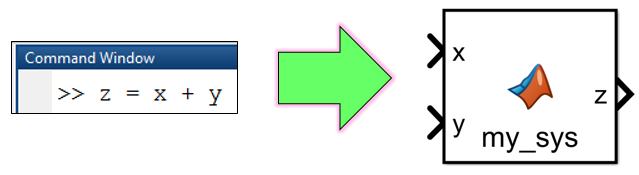

To use/solve these derived equations of motion we'll create a MATLAB Function block that can be used inside Simulink:

lag_OBJ.create_MLF_blocks()

# Create  some REusable functions from our expressions:

tf_i_should_create_SL_block = false;
if(true==tf_i_should_create_SL_block)
    MODEL_NAME = 'bh_tmp_model_for_lagr';
    if(4==exist(MODEL_NAME))
        close_system(MODEL_NAME, 0);
        delete(MODEL_NAME);
    end
    new_system(MODEL_NAME)
    open_system(MODEL_NAME)   
                          
    % do the bRg block first
    BLOCK_NAME      = [MODEL_NAME,'/bRg'];  
    INPUT_VAR_ORDER = {'phi','theta','psi'};
    matlabFunctionBlock(BLOCK_NAME, bRg, 'Optimize',false, 'Vars', INPUT_VAR_ORDER);    
    set_param(BLOCK_NAME,'BackgroundColor', '[0.996078, 1.000000, 0.705882]'); 
           
    % The EULER and BODY rate conversions - part 1 of 2 
    tmp_holder      = [lag_OBJ.holder_list_SYM_pos; lag_OBJ.holder_list_SYM_vel; lag_OBJ.holder_list_SYM_acc];
    tmp_actual      = [lag_OBJ.actual_list_SYM_pos; lag_OBJ.actual_list_SYM_vel; lag_OBJ.actual_list_SYM_acc];
       
    BLOCK_NAME      = [MODEL_NAME,'/calc_w_from_eul_rates'];  
    w               = A * e_dot; 
    w               = subs(w, tmp_actual, tmp_holder);
    w               = simplify(  formula( w )   );
    matlabFunctionBlock( BLOCK_NAME, w, 'Optimize',false,   ...
                         'Vars',  {'THE_Theta','THE_Psi','THE_Phi_D','THE_Theta_D','THE_Psi_D'}, ...        
                         'Outputs', {'wb'} ); 
    set_param(BLOCK_NAME,'BackgroundColor', '[0.996078, 1.000000, 0.705882]'); 
       
    % The EULER and BODY rate conversions - part 2 of 2        
    BLOCK_NAME      = [MODEL_NAME,'/calc_eul_rates_from_w'];
    syms p q r
    e_dot           = inv(A) * [p;q;r]; 
    e_dot           = subs(e_dot, tmp_actual, tmp_holder);
    e_dot           = simplify(  formula( e_dot )  );
    matlabFunctionBlock( BLOCK_NAME, e_dot, 'Optimize',false, ...
                         'Vars', {'THE_Theta','THE_Psi','p','q','r'}, ...
                         'Outputs', {'edot'} );
    set_param(BLOCK_NAME,'BackgroundColor', '[0.996078, 1.000000, 0.705882]');     
end

# Am curious how/where the motor speeds appear in the Eom:

Recall our list of motor speed symbols:

wMOT_list

$$wMOT\_list = \left(\begin{array}{c} {\mathrm{wMOT}}_{1}\\ {\mathrm{wMOT}}_{2}\\ {\mathrm{wMOT}}_{3}\\ {\mathrm{wMOT}}_{4} \end{array}\right)$$

And recall how the `coeffs()` function works:

- `syms x`

- `f = 100*x^2 -34*x + 90;`

- `[C,T] = coeffs(f, x, 'All')`

- `C =  [ 100, -34, 90]`

- `T =  [ x^2, x, 1]`

So look for these symbols in our RHS of the eoms:

for jj=1:length(holder_list_SYM_pos)
  fprintf('\n ------------------------------------------');
  fprintf('\n [RHS_EOM_%d]: %s', jj, char(holder_list_SYM_pos(jj)) );       

  the_eom = lag_OBJ.get_eom(jj, 'holder', 'RHS');
  the_eom = expand( the_eom );


   for kk=1:length(wMOT_list)
       wsymbol =  wMOT_list(kk);
       
       [C, T]      = coeffs(the_eom, wsymbol, 'All');
       
       if(1==length(C))
          fprintf('\n    [MOT_#%d]: %s --->>> 0', kk, char(wsymbol) ); 
       else
          tmp_expr = C(1:end-1) .* T(1:end-1);
          fprintf('\n    [MOT_#%d]: %s --->>> %s', kk, char(wsymbol), char(tmp_expr) ); 
       end
   end
end


 ------------------------------------------


 [RHS_EOM_1]: THE_Phi


    [MOT_#1]: wMOT_1 --->>> 0
    [MOT_#2]: wMOT_2 --->>> 0
    [MOT_#3]: wMOT_3 --->>> 0
    [MOT_#4]: wMOT_4 --->>> 0


 ------------------------------------------


 [RHS_EOM_2]: THE_Theta


    [MOT_#1]: wMOT_1 --->>> 0
    [MOT_#2]: wMOT_2 --->>> 0
    [MOT_#3]: wMOT_3 --->>> 0
    [MOT_#4]: wMOT_4 --->>> 0


 ------------------------------------------


 [RHS_EOM_3]: THE_Psi


    [MOT_#1]: wMOT_1 --->>> 0
    [MOT_#2]: wMOT_2 --->>> 0
    [MOT_#3]: wMOT_3 --->>> 0
    [MOT_#4]: wMOT_4 --->>> 0


 ------------------------------------------


 [RHS_EOM_4]: THE_X


    [MOT_#1]: wMOT_1 --->>> 0
    [MOT_#2]: wMOT_2 --->>> 0
    [MOT_#3]: wMOT_3 --->>> 0
    [MOT_#4]: wMOT_4 --->>> 0


 ------------------------------------------


 [RHS_EOM_5]: THE_Y


    [MOT_#1]: wMOT_1 --->>> 0
    [MOT_#2]: wMOT_2 --->>> 0
    [MOT_#3]: wMOT_3 --->>> 0
    [MOT_#4]: wMOT_4 --->>> 0


 ------------------------------------------


 [RHS_EOM_6]: THE_Z


    [MOT_#1]: wMOT_1 --->>> 0
    [MOT_#2]: wMOT_2 --->>> 0
    [MOT_#3]: wMOT_3 --->>> 0
    [MOT_#4]: wMOT_4 --->>> 0

So look for these symbols in our LHS of the eoms:

for jj=1:length(holder_list_SYM_pos)
  fprintf('\n ------------------------------------------');
  fprintf('\n [LHS_EOM_%d]: %s', jj, char(holder_list_SYM_pos(jj)) );       

  the_eom = lag_OBJ.get_eom(jj, 'holder', 'LHS');
  the_eom = expand( the_eom );


   for kk=1:length(wMOT_list)
       wsymbol =  wMOT_list(kk);
       
       [C, T]      = coeffs(the_eom, wsymbol, 'All');
       
       if(1==length(C))
          fprintf('\n    [MOT_#%d]: %s --->>> 0', kk, char(wsymbol) ); 
       else
          tmp_expr = C(1:end-1) .* T(1:end-1);
          %fprintf('\n    [MOT_#%d]: %s --->>> %s', kk, char(wsymbol), char(tmp_expr) ); 
          % now let's also suppose that the cross moment of inertia
          % terms of our propeller assembly are ZERO
          tmp_expr = subs(tmp_expr, [Iprop_xy, Iprop_xz, Iprop_yz], [0,0,0]);

          tmp_expr = simplify(tmp_expr);
          fprintf('\n    [MOT_#%d]: %s --->>> %s', kk, char(wsymbol), char(tmp_expr) ); 
       end
   end
end


 ------------------------------------------


 [LHS_EOM_1]: THE_Phi


    [MOT_#1]: wMOT_1 --->>> -Iprop_zz*wMOT_1*(THE_Psi_D*cos(THE_Theta)*sin(THE_Psi) + THE_Theta_D*cos(THE_Psi)*sin(THE_Theta))
    [MOT_#2]: wMOT_2 --->>> -Iprop_zz*wMOT_2*(THE_Psi_D*cos(THE_Theta)*sin(THE_Psi) + THE_Theta_D*cos(THE_Psi)*sin(THE_Theta))
    [MOT_#3]: wMOT_3 --->>> -Iprop_zz*wMOT_3*(THE_Psi_D*cos(THE_Theta)*sin(THE_Psi) + THE_Theta_D*cos(THE_Psi)*sin(THE_Theta))
    [MOT_#4]: wMOT_4 --->>> -Iprop_zz*wMOT_4*(THE_Psi_D*cos(THE_Theta)*sin(THE_Psi) + THE_Theta_D*cos(THE_Psi)*sin(THE_Theta))


 ------------------------------------------


 [LHS_EOM_2]: THE_Theta


    [MOT_#1]: wMOT_1 --->>> -Iprop_zz*wMOT_1*cos(THE_Psi)*(THE_Psi_D - THE_Phi_D*sin(THE_Theta))
    [MOT_#2]: wMOT_2 --->>> -Iprop_zz*wMOT_2*cos(THE_Psi)*(THE_Psi_D - THE_Phi_D*sin(THE_Theta))
    [MOT_#3]: wMOT_3 --->>> -Iprop_zz*wMOT_3*cos(THE_Psi)*(THE_Psi_D - THE_Phi_D*sin(THE_Theta))
    [MOT_#4]: wMOT_4 --->>> -Iprop_zz*wMOT_4*cos(THE_Psi)*(THE_Psi_D - THE_Phi_D*sin(THE_Theta))


 ------------------------------------------


 [LHS_EOM_3]: THE_Psi


    [MOT_#1]: wMOT_1 --->>> Iprop_zz*wMOT_1*(THE_Theta_D*cos(THE_Psi) + THE_Phi_D*cos(THE_Theta)*sin(THE_Psi))
    [MOT_#2]: wMOT_2 --->>> Iprop_zz*wMOT_2*(THE_Theta_D*cos(THE_Psi) + THE_Phi_D*cos(THE_Theta)*sin(THE_Psi))
    [MOT_#3]: wMOT_3 --->>> Iprop_zz*wMOT_3*(THE_Theta_D*cos(THE_Psi) + THE_Phi_D*cos(THE_Theta)*sin(THE_Psi))
    [MOT_#4]: wMOT_4 --->>> Iprop_zz*wMOT_4*(THE_Theta_D*cos(THE_Psi) + THE_Phi_D*cos(THE_Theta)*sin(THE_Psi))


 ------------------------------------------


 [LHS_EOM_4]: THE_X


    [MOT_#1]: wMOT_1 --->>> 0
    [MOT_#2]: wMOT_2 --->>> 0
    [MOT_#3]: wMOT_3 --->>> 0
    [MOT_#4]: wMOT_4 --->>> 0


 ------------------------------------------


 [LHS_EOM_5]: THE_Y


    [MOT_#1]: wMOT_1 --->>> 0
    [MOT_#2]: wMOT_2 --->>> 0
    [MOT_#3]: wMOT_3 --->>> 0
    [MOT_#4]: wMOT_4 --->>> 0


 ------------------------------------------


 [LHS_EOM_6]: THE_Z


    [MOT_#1]: wMOT_1 --->>> 0
    [MOT_#2]: wMOT_2 --->>> 0
    [MOT_#3]: wMOT_3 --->>> 0
    [MOT_#4]: wMOT_4 --->>> 0

# **Local functions:**

For a refresher on the concept of Euler rates and their relationship to the angular velocity of a body, please review the stand alone Live script called:

- `bh_review_Euler_rates_and_wb.mlx `

The function below runs the above script and returns some of the symbols defined in the script.  When we call the script from inside the function, the variables created by the script are created in the "local" function workspace.

function [bRg, A] = LOC_collect_euler_concepts()
    
    % run the script inside our function
    bh_review_Euler_rates_and_wb
    
end

The cross product

function c = cross(a,b)

    c1 = a(2).*b(3)-a(3).*b(2);
    c2 = a(3).*b(1)-a(1).*b(3);
    c3 = a(1).*b(2)-a(2).*b(1);

    c  = [c1;c2;c3]; 

end